clear;

## capacitor voltage

Cc = 10e-3; 
% input params
t1 = 10e-3; t2 = 0.75; % input step times
V1 = 15; V2 = 15; % the DC-DC converter output voltages (corresponding to battery SOCs)
Io = 10; % output current
io = @(t) 2*Io*heaviside(t - t1) + Io; % input currents

cap_sys = @(t,y) 1/Cc * (Io - io(t));
% simulation 
tspan = [0 20e-3];
y0 = [0];
[t,y] = ode45(@(t,y) cap_sys(t,y),tspan,y0);

## Considering 2-parallel DC-DC convertes

L1 = 1e-3; L2 = 1e-3; % filter inductance of every DC-DC converter
Cc = 10e-3; % DC-link cpacitor
% state equations
A = 0;
B = -1/Cc;

% input params
t1 = 0.5; t2 = 0.75; % input step times
V1 = 15; V2 = 15; % the DC-DC converter output voltages (corresponding to battery SOCs)
Io = 10; % output current
io = @(t) 2*Io*heaviside(t - t1) + Io; % input currents
v1 = @(t) V1; % converter voltages
v2 = @(t) V2; % converter voltages
u = @(t) [io(t)]';

Reindl_sys = @(t,y) A*y + 10 + B*u(t);

% simulation 
tspan = [0 1e-3];
y0 = [0];
[t,y] = ode45(@(t,y) Reindl_sys(t,y),tspan,y0);

## plots

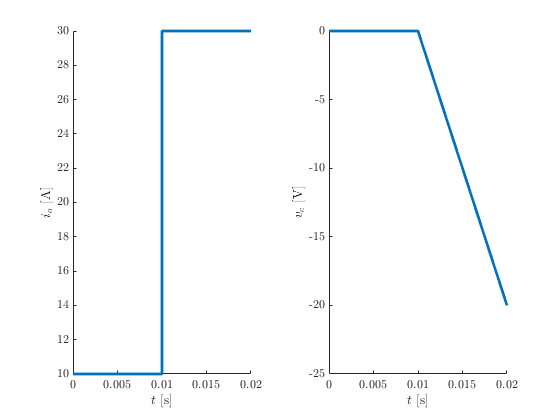

figure(1); clf;
tiledlayout(1,2)

ax(1) = nexttile; 
plot(t,io(t),'LineWidth',2); box off
ylabel('$i_o$ [A]','Interpreter',"latex");
xlabel('$t$ [s]','Interpreter',"latex");

ax(2) = nexttile; 
plot(t,y(:,1),'LineWidth',2); box off
ylabel('$v_c$ [V]','Interpreter',"latex");
xlabel('$t$ [s]','Interpreter',"latex");

% ax(3) = nexttile; 
% plot(t,y(:,2),'LineWidth',2); box off
% ylabel('$i_1$ [A]','Interpreter',"latex");
% xlabel('$t$ [s]','Interpreter',"latex");

% ax(2) = nexttile; 
% plot(t,y(:,3),'LineWidth',2); box off
% ylabel('$i_1$ [A]','Interpreter',"latex");
% xlabel('$t$ [s]','Interpreter',"latex");

% Get latex font in ticks
h = findall(gcf,'Type','axes'); % An array if you have subplots
set(h, 'TickLabelInterpreter', 'latex')


% % saving plots
% textwidth = 13.6;
% golden_ratio = (1 + sqrt(5)) / 2 ;
% textheight = textwidth / golden_ratio * 1.5;
% figsize = [textwidth, textheight];
% 
% % Set size and no crop
% set(gcf, 'PaperUnits', 'centimeters', 'PaperSize', figsize);
% set(gcf, 'PaperUnits', 'normalized', 'PaperPosition', [0, 0, 1, 1]);
